# What Kind of Flower is That?

This example uses transfer learning to train a deep network that can classify images of flowers into one of 12 species.

## Get training images

flowerds = imageDatastore('Flowers','IncludeSubfolders',true,'LabelSource','foldernames');

Split into training and testing sets

[trainImgs,testImgs] = splitEachLabel(flowerds,0.6);

Determine the number of flower species

numClasses = numel(categories(flowerds.Labels));

## Create a network by modifying AlexNet

Get the layers from AlexNet

net = alexnet;
layers = net.Layers;

Modify the classification and output layers

layers(end-2) = fullyConnectedLayer(numClasses);
layers(end) = classificationLayer;

## Set training algorithm options

Lower the learning rate for transfer learning

options = trainingOptions('sgdm','InitialLearnRate', 0.001);

## Perform training

[flowernet,info] = trainNetwork(trainImgs, layers, options);

Training on single GPU.
Initializing image normalization.
|=========================================================================================|
|     Epoch    |   Iteration  | Time Elapsed |  Mini-batch  |  Mini-batch  | Base Learning|
|              |              |  (seconds)   |     Loss     |   Accuracy   |     Rate     |
|=========================================================================================|
|            1 |            1 |         0.44 |       3.3921 |       10.94% |       0.0010 |
|           13 |           50 |        37.13 |       0.0076 |      100.00% |       0.0010 |
|           25 |          100 |        73.79 |       0.0071 |      100.00% |       0.0010 |
|           30 |          120 |        87.50 |       0.0017 |      100.00% |       0.0010 |
|=========================================================================================|


## Use the trained network to classify test images

testpreds = classify(flowernet,testImgs);

## Evaluate the results

Calculate the accuracy

nnz(testpreds == testImgs.Labels)/numel(testpreds)

ans = 0.8854

Visualize the confusion matrix

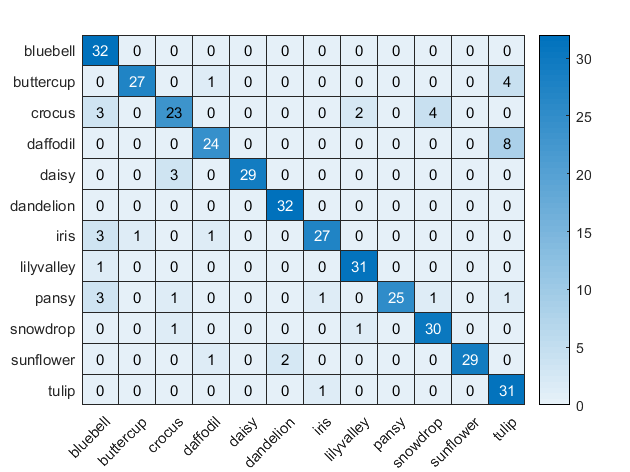

[flowerconf,flowernames] = confusionmat(testImgs.Labels,testpreds);
heatmap(flowernames,flowernames,flowerconf);